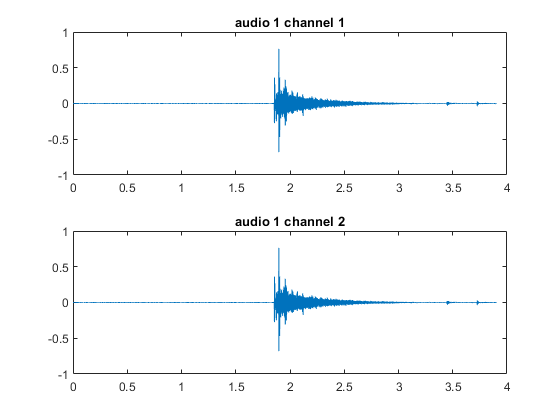

% Preliminary example
N=25; % length of data vector
n=1:N; % indices
h(n)=1.05.^(n); % impulse response (growing)
x=zeros(N,1); % initializes x, the input.
x(10) = 1; % replaces the first value of x with 1; happens to be an impulse
x(2:6) = 1;
y=conv(x,h); % conv performs convolution stem(y(1:N))

% read in the impulse response
[Y1,FS1] = audioread('impulse1.wav');

[Y2,FS2] = audioread("03 - The Andy Griffith Show(1).mp3");

% read out right and left channels
Y1a=Y1(:,1);
Y1b=Y1(:,2);

Y2a=Y2(:,1);
Y2b=Y2(:,2);

% define the impulse response to be one of the channels
h1 = Y1a; 
h2 = Y2a;

%time vector
N1=length(Y1a);
Ts1=1/FS1;
time1=(1:N1)*Ts1;

N2=length(Y2a);
Ts2=1/FS2;
time2=(1:N2)*Ts2;

%plot data
subplot(2,1,1), plot(time1, Y1a);
title("audio 1 channel 1");
subplot(2,1,2), plot(time1, Y1b);
title("audio 1 channel 2");

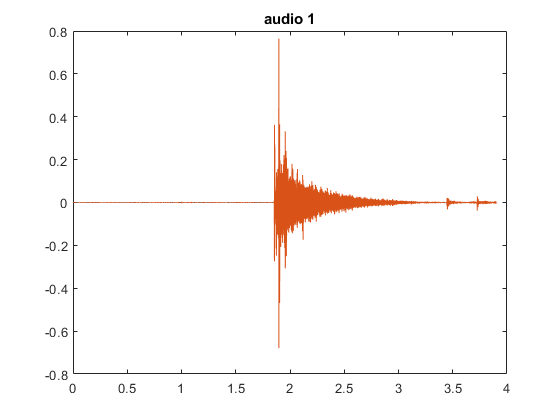

figure;
plot(time1, Y1a, time1, Y1b);
title("audio 1");

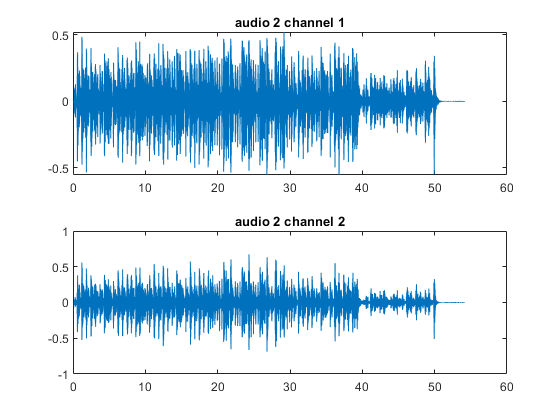

figure;
subplot(2,1,1), plot(time2, Y2a);
title("audio 2 channel 1");
subplot(2,1,2), plot(time2, Y2b);
title("audio 2 channel 2");

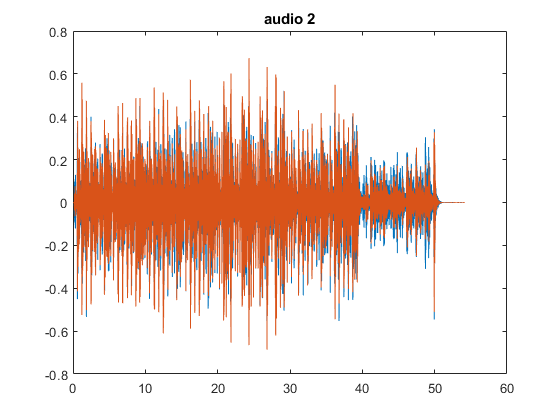

figure;
plot(time2, Y2a, time2, Y2b);
title("audio 2");

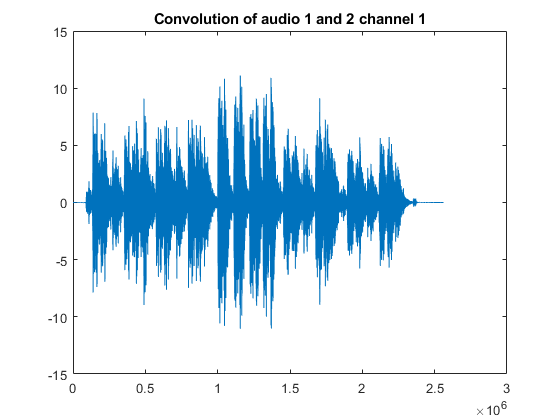


%convolve
c1 = conv(Y1a, Y2a);
c2 = conv(Y1b, Y2b);

%plot convolution
plot(c1);
title("Convolution of audio 1 and 2 channel 1");

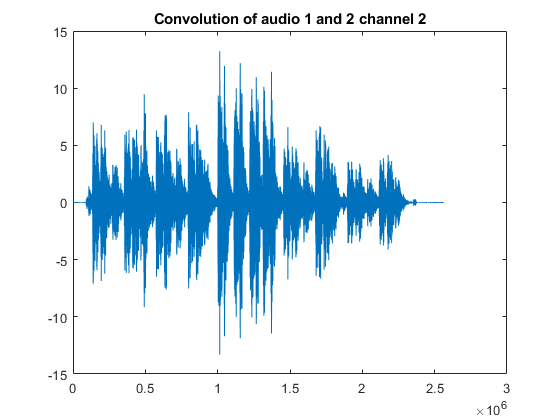

figure;
plot(c2);
title("Convolution of audio 1 and 2 channel 2");


% use the sound command to listen to the original and convolved outputs
soundsc(c1, 44100)